# ROS Robot Motion Control

## Modeling and Control of Robotic Manipulators

Reminder: Follow the steps in the instruction files in the moodle course for using VM, ROS and Matlab.

**Recommended Matlab Version: 2022b**

## Inverse Kinematics

#### 1.	Inverse Kinematics

Generate an **inverse kinematics solver** object `iksolver` for the rigid body tree object *ur*.

% Import the UR10 robot model from a URDF file
ur10=importrobot('ur10.urdf');
ur10.showdetails();

--------------------
Robot: (8 bodies)

 Idx             Body Name                 Joint Name                 Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                 ----------                 ----------             ----------------   ----------------
   1             base_link                world_joint                      fixed                     world(0)   shoulder_link(2)  
   2         shoulder_link         shoulder_pan_joint                   revolute                 base_link(1)   upper_arm_link(3)  
   3        upper_arm_link        shoulder_lift_joint                   revolute             shoulder_link(2)   forearm_link(4)  
   4          forearm_link                elbow_joint                   revolute            upper_arm_link(3)   wrist_1_link(5)  
   5          wrist_1_link              wrist_1_joint                   revolute              forearm_link(4)   wrist_2_link(6)  
   6          wrist_2_link              wrist_2_j

% Create an Inverse Kinematics (IK) solver for the UR10 robot
% The solver is based on the "rigidBodyTree" representation of the robot
ikur10 = robotics.InverseKinematics('RigidBodyTree',ur10);
% The IK solver (ikur10) will be used to compute joint angles for a given
% end-effector position and orientation (pose).

#### 2.	Define a target pose

Define a target pose in terms of a transform *tformTargetPose* that results from a translation $$[d_x \ d_y \ d_z]^T =[0.6 \ 0 \ 1.0]^T$$ and a rotation by Euler angles $$[\phi \ \theta \ \psi]^T=[\pi/4  \ \pi/4  \ -\pi/4]^T$$.	

% Define the target position of the end-effector (X, Y, Z in meters)
targetPosition=[0.6, 0, 1.0];
% Define the target orientation using Euler angles (ZYZ convention in radians)
targetOrientation=[pi/4, pi/4, -pi/4];
% Compute the final target pose as a 4x4 homogeneous transformation matrix.

% Convert position to a transformation matrix
t1=trvec2tform(targetPosition);
% Convert Euler angles to a rotation transformation matrix
t2=eul2tform(targetOrientation, "ZYZ");

% Combine translation and rotation into a single transformation matrix
targetposeur10=t1*t2;

% Display the final transformation matrix
disp('Target Pose Transformation Matrix:');

Target Pose Transformation Matrix:


disp(targetposeur10);

    0.8536   -0.1464    0.5000    0.6000
   -0.1464    0.8536    0.5000         0
   -0.5000   -0.5000    0.7071    1.0000
         0         0         0    1.0000



#### 3.    Determine the targetConf with the initialized ikSolver object above

Determine the inverse kinematics solution *targetConf* with the method `ik` for the target pose of the end effector link frame *'ee_link'* with a unit error weight vector $$w=[1 \ 1 \ 1 \ 1 \ 1 \ 1]$$. 

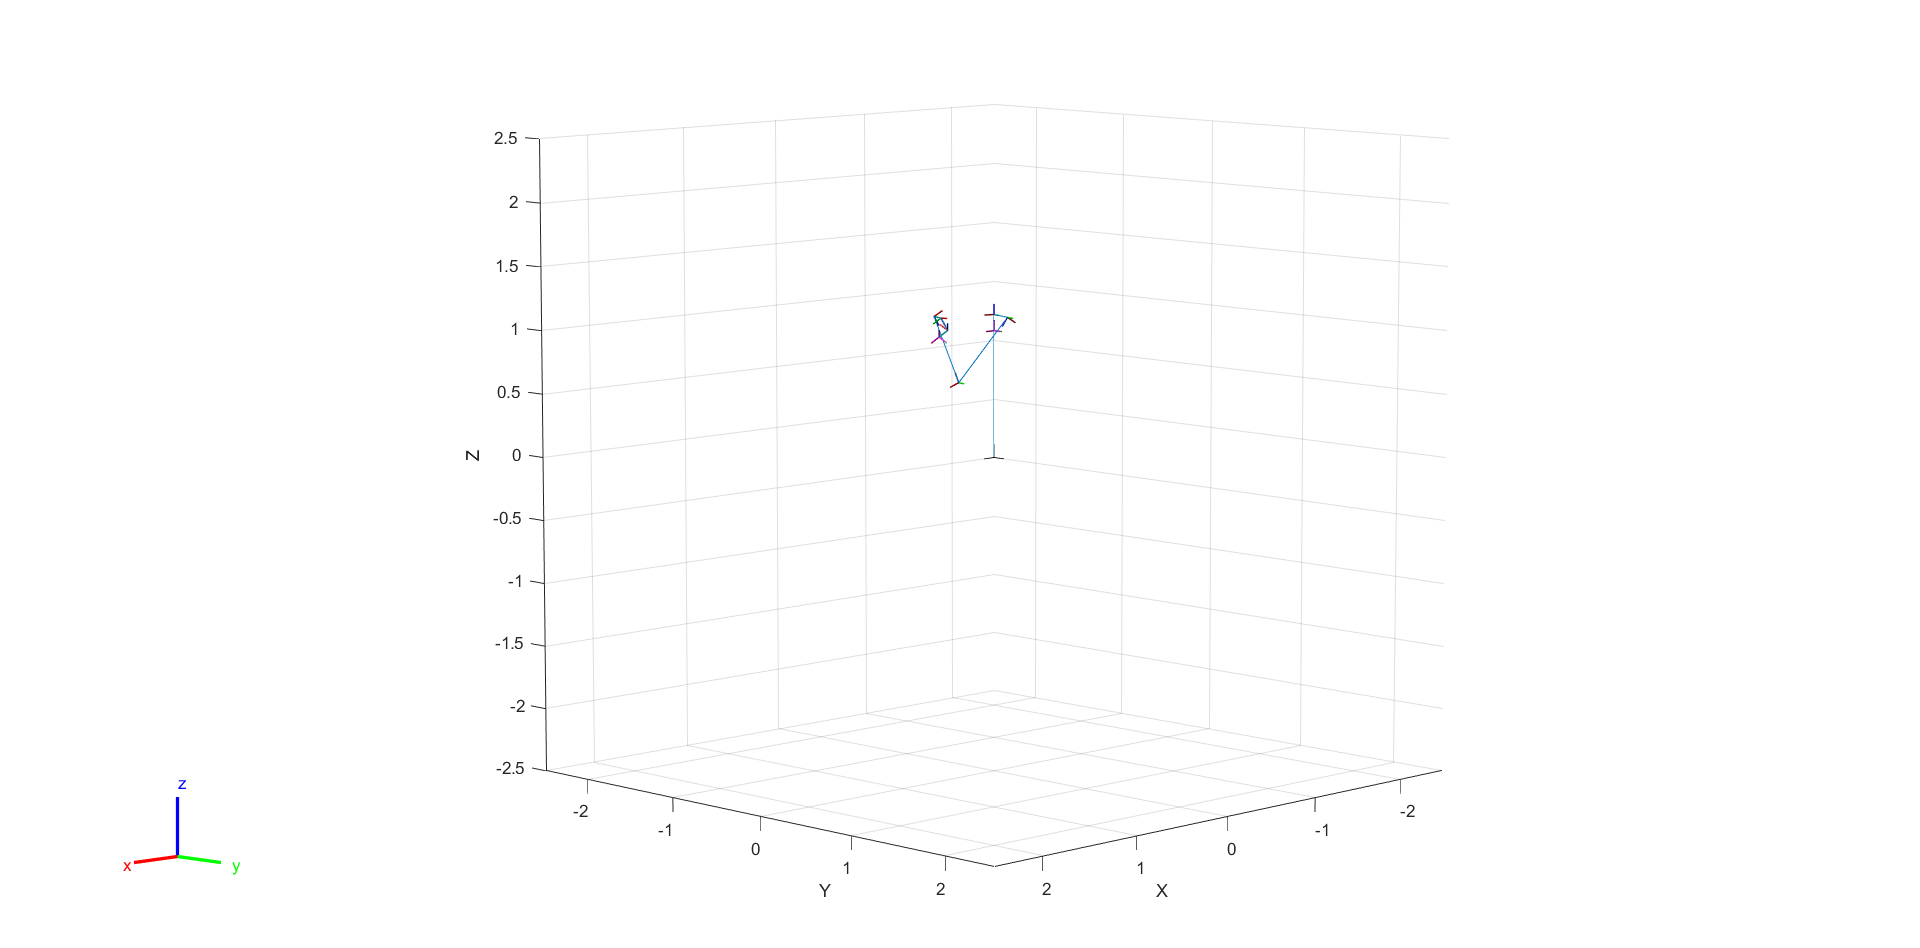

% Define the weightings for the inverse kinematics solver.
%Creates a 6x1 vector [1; 1; 1; 1; 1; 1] indicating equal priority on 
   % minimizing errors in X, Y, Z positions and the three orientation angles.
weights = ones(6,1);
% Define an initial joint configuration as a starting guess for the IK solver
initialpose = JointVec2JointConf(ur10,[0 1 -2 2 1 1]);
%numerical vector representing joint angles [q1, q2, q3, q4, q5, q6] in radians.
% Solve the inverse kinematics problem:
[targetsol, solnInfo] = ikur10('ee_link', targetposeur10 ,weights,initialpose);
ur10.show(targetsol);

disp (solnInfo);

           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2577e-08
             ExitFlag: 1
               Status: 'success'



## ROS

#### 4.    Simulate the UR robot motion in Gazebo

To simulate the UR robot motion in Gazebo invoke the following launch files:

		`roslaunch ur_launch ur10_sim_gazebo.launch rqt:=false`

The launch file starts Gazebo (hidden), RViz and the ROS controllers without the RQT interface.	

#### 5.    Connect to ROS

Connect to the ROS master on the local host from within Matlab with `rosinit`

rosshutdown
rosinit('100.64.87.6')

Initializing global node /matlab_global_node_36109 with NodeURI http://100.64.125.101:49269/ and MasterURI http://100.64.87.6:11311.


#### 6.    Show topics

Query the topics that are currently available on the network and obtain information about the topic *'/ur10/joint_states'* in particular the message type.

You notice that the *JointStatePublisher* publishes on the topic *'/ur10/joint_states'*

rostopic list

/clicked_point                                                                      
/clock                                                                              
/gazebo/link_states                                                                 
/gazebo/model_states                                                                
/gazebo/parameter_descriptions                                                      
/gazebo/parameter_updates                                                           
/gazebo/performance_metrics                                                         
/gazebo/set_link_state                                                              
/gazebo/set_model_state                                                             
/initialpose                                                                        
/move_base_simple/goal                                                              
/robot_workspace_monitor/dynamic_obstacle_marker                 

rostopic info /ur10/joint_states

Type: sensor_msgs/JointState
 
Publishers:
* /gazebo (http://100.64.87.6:38003/)
 
Subscribers:
* /robot_state_publisher (http://100.64.87.6:41703/)


rostopic info ur10/vel_based_pos_traj_controller/command

Type: trajectory_msgs/JointTrajectory
 
Publishers:
 
Subscribers:
* /gazebo (http://100.64.87.6:38003/)


rostopic info /tf_static

Type: tf2_msgs/TFMessage
 
Publishers:
* /scene_state_publisher (http://100.64.87.6:41893/)
* /robot_state_publisher (http://100.64.87.6:41703/)
 
Subscribers:
* /rviz (http://100.64.87.6:42619/)


#### 7.    Instantiate a subscriber for the topic above and receive messages

Instantiate a subscriber in Matlab for this topic and receive a message for the joint states.

Inspect the field *jointstate.Position* which denotes the vector of joint variables. The first six elements correspond to joints *shoulder_pan_joint*` to `*wrist_3_joint*`.`

% Create a subscriber for the 'joint_states' topic
jointStateSub = rossubscriber('/ur10/joint_states', 'sensor_msgs/JointState');

% Receive a message from the topic (with a 10-second timeout)
jointStateMsg = receive(jointStateSub, 10);
disp (jointStateMsg);

  ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {6×1 cell}
       Position: [6×1 double]
       Velocity: [6×1 double]
         Effort: [6×1 double]

  Use showdetails to show the contents of the message



% Extract joint positions
jointPositions = jointStateMsg.Position;
% Display the first six joint positions (shoulder_pan_joint to wrist_3_joint)
disp('Joint Positions (Shoulder to Wrist):');

Joint Positions (Shoulder to Wrist):


disp(jointPositions(1:6));

     0
     0
     0
     0
     0
     0



## Trajectory Control via Topic Interface

#### 8.    Information about ros message and helper function

Trajectory commands of message type *trajectory_msgs/JointTrajectory* are published on the topic  */ur10/vel_based_pos_traj_controller/command. *Instantiate a message object and inspect the message type structure

`	jointCommandMsg=rosmessage('trajectory_msgs/JointTrajectory')	`

The message type has the components *Header*, *JointNames* and *Points*. *JointNames* refer to the joint names in the URDF description of the robot. *Points* is an array of waypoints (*JointTrajectoryPoint*) that constitutes the sequence of poses plus time intervals the robot is supposed to track. Each *JointTrajectoryPoint* of message type *trajectory_msgs/TrajectoryPoint* has the components *Positions*, *Velocities* and *Accelerations* which correspond to joint state vector $$\mathbf{q}$$, joint velocity vector $$\dot{\mathbf{q}}$$ and joint acceleration vector $$\ddot{\mathbf{q}}$$. The component *TimeFromStart* specifies the time stamp of the waypoint, relative to the message time defined in the header of the *trajectory_msgs/JointTrajectory* message.

The helper function 	

		`function [ jointTrajectoryMsg ] = JointVec2JointTrajectoryMsg(robot, q, t, qvel, qacc)`

maps the  $$n \times m$$ arrays of joint vectors *q*,  joint velocities *qvel* and joint accelerations *qacc* and the $$n \times 1$$ vector of time stamps onto the corresponding joint trajectory message. The input argument *qvel* and *qacc* are optional and assume default zero values if omitted. 

#### 9.    Perform a point to point motion

Perform a point-to-point motion from the current configuration to the target configuration from task 3.	


% Create a ROS publisher for trajectory control
jointTrajectoryPub = rospublisher('/ur10/vel_based_pos_traj_controller/command', ...
    'trajectory_msgs/JointTrajectory');
% Extract joint positions (q_target) from the computed target configuration
q_target = [targetsol.JointPosition]; 
% Vector of joint positions from 'targetsol'

%Define the trajectory timing
t_target = 2.5; % Duration to reach the target configuration (seconds)
t_offset = 3; % Additional time to allow motion to complete

% Generate the trajectory message
q_start = [ur10.homeConfiguration.JointPosition]; % home configuration
disp (q_start);

     0     0     0     0     0     0



% Define trajectory timing
t = [0; t_target]; % Start and end times

% Create trajectory waypoints
q = [q_start; q_target]; % Start and target configurations
qvel = zeros(size(q)); % Assume zero velocities
qacc = zeros(size(q)); % Assume zero accelerations
disp (q);

         0         0         0         0         0         0
   -0.2939    0.9881   -2.1710    1.7099    1.4635    2.4639



% Use the helper function to generate the joint trajectory message
jointTrajectoryMsg = JointVec2JointTrajectoryMsg(ur10, q, t, qvel, qacc);
% Prepares the command for execution.

% Send the trajectory message to the robot
send(jointTrajectoryPub, jointTrajectoryMsg);
%  Initiates the motion in a “fire-and-forget” manner.

pause(t_target + t_offset); % Wait for the robot to complete the motion
disp('Robot is in the target configuration.');

Robot is in the target configuration.


#### 10.    Execute the rated loop that monitors the temporal evaluation of the joint state vector

The motion command is executed in a fire and forget manner. Replace the `pause` command with a rated loop that monitors the temporal evolution of the joint state vector by subscribing to the */ur10/joint_states* topic. 

The helper function

`	function [ jointState, jointVel ] = JointStateMsg2JointState( robot, jointMsg )	`

converts a joint state message into joint state and joint velocity vectors.

%Define home configuration and move robot to start position
q_home = [0 0 0 0 0 0]; % Home position
t_home = 2.5; % Time to reach home position
t_offset = 3; % Extra time buffer

% Create a ROS publisher for trajectory control
jointTrajectoryPub = rospublisher('/ur10/vel_based_pos_traj_controller/command', ...
    'trajectory_msgs/JointTrajectory');
% Move robot to home position
send(jointTrajectoryPub, JointVec2JointTrajectoryMsg(ur10, q_home, t_home));
% Create a subscriber to monitor joint states
jointStateSub = rossubscriber('/ur10/joint_states', 'sensor_msgs/JointState');
% Wait for the robot to settle in the home position
pause(t_home + t_offset); % Allow time for motion to complete

% Define the new target configuration and move the robot
q_target = [targetsol.JointPosition]; % Extract target joint positions
t_target = 2.5; % Motion duration
% Send the motion command
send(jointTrajectoryPub, JointVec2JointTrajectoryMsg(ur10, q_target, t_target));
% Similar to Task 9, but now followed by active monitoring.

% Execute rated loop to monitor joint states
rate = 100; % Hz
rateObj = robotics.Rate(rate); %an object to control loop timing.
tf = t_target + 2.0; % Monitor for slightly longer than the motion time
rateObj.reset(); % Reset time tracking
%Ensures consistent sampling for smooth data collection.

% Preallocate arrays for logging
N = tf * rate; % Total number of iterations
timeStamp = zeros(N, 1);
jointStateStamped = zeros(N, 6); % Store joint positions
jointVelStamped = zeros(N, 6); % Store joint velocities

% Store start time
jointStateMsg = receive(jointStateSub); % Get initial message
t0 = double(jointStateMsg.Header.Stamp.Sec) + ...
     double(jointStateMsg.Header.Stamp.Nsec) * 10^-9; % Convert to seconds

% Start monitoring loop for Collecting joint data at 50 Hz over 4.5 seconds.
for i = 1:N
    % Receive latest joint state message
    jointStateMsg = receive(jointStateSub);
    
    % Convert message to joint state and velocity
    [jointState, jointVel] = JointStateMsg2JointState(ur10, jointStateMsg);
    
    % Store data
    jointStateStamped(i, :) = jointState;
    jointVelStamped(i, :) = jointVel;
    timeStamp(i) = double(jointStateMsg.Header.Stamp.Sec) + ...
                   double(jointStateMsg.Header.Stamp.Nsec) * 10^-9 - t0;
    
    % Maintain loop rate
    waitfor(rateObj);
end


#### 11.    Plot the joint state and joint velocity

Plot the joint state and joint velocity vector versus time as shown in figure 3. The joint motion profile is quintic to guarantee continuity of joint state, velocities and accelerations at way-points.

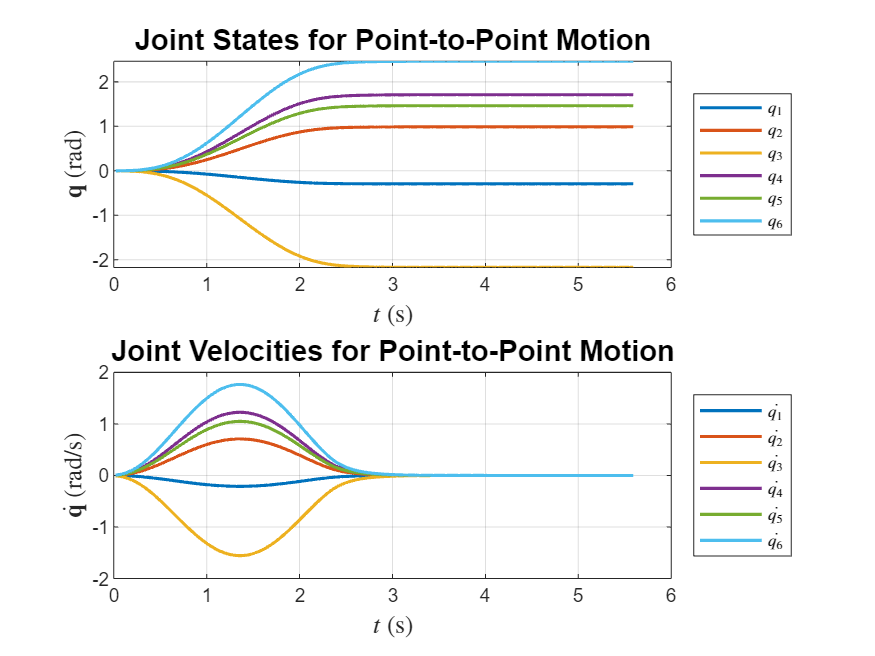

% Task 11: Plot Joint States and Velocities

figure(1);
clf; % Clear figure

% Plot joint positions
subplot(2,1,1);
plot(timeStamp, jointStateStamped, 'LineWidth', 1.5);
xlabel('$t$ (s)','Interpreter','Latex', 'FontSize', 12);
ylabel('$\mathbf{q}$ (rad)','Interpreter','Latex', 'FontSize', 12);
legend({'$q_1$','$q_2$','$q_3$','$q_4$','$q_5$','$q_6$'}, 'Interpreter', 'Latex', 'FontSize', 8, 'Location', 'eastoutside');
title('Joint States for Point-to-Point Motion', 'FontSize', 14);
grid on;

% Plot joint velocities
subplot(2,1,2);
plot(timeStamp, jointVelStamped, 'LineWidth', 1.5);
xlabel('$t$ (s)','Interpreter','Latex', 'FontSize', 12);
ylabel('$\dot{\mathbf{q}}$ (rad/s)','Interpreter','Latex', 'FontSize', 12);
legend({'$\dot{q_1}$','$\dot{q_2}$','$\dot{q_3}$','$\dot{q_4}$','$\dot{q_5}$','$\dot{q_6}$'}, 'Interpreter', 'Latex', 'FontSize', 8, 'Location', 'eastoutside');
title('Joint Velocities for Point-to-Point Motion', 'FontSize', 14);
grid on;

#### 12.    Prepare a motion via two way-points

A general trajectory is composed of a sequence of way-points. The joint trajectory commands accept multiple joint configurations with time stamps to be traversed in that order. Command a trajectory  composed of the intermediate way-point $$\mathbf{q}_{target}$ and final way-point $$\mathbf{q}_2=[-1 \ 0 \ -1 \ 1 \ 0 \ 2]$$. 

% Define home configuration and move robot to start position
q_home = [0 0 0 0 0 0]; % Home position
t_home = 2.5; % Time to reach home position


% Create a ROS publisher for trajectory control
jointTrajectoryPub = rospublisher('/ur10/vel_based_pos_traj_controller/command', ...
    'trajectory_msgs/JointTrajectory');

% Move robot to home position
send(jointTrajectoryPub, JointVec2JointTrajectoryMsg(ur10, q_home, t_home));

% Define waypoints, time targets, and velocities
t_targets = [2.5; 6.0];   % Time to reach intermediate and final waypoints
qf = [-1 0 -1 1 0 2]; % Final waypoint configuration
q_targets = [q_target; qf]; % Combine intermediate waypoint (q_target) and final waypoint (qf)

% Define velocities (set to zeros initially)
qvel = zeros(size(q_targets));  % Stop at both waypoints

% Save trajectory parameters for Task 12
save('trajectory_params.mat', 'q_targets', 't_targets', 'qvel');  % Save waypoints, time targets, and velocities
pause(10);

#### 13.	Perform motion via two or more way-points

Command, record and plot the joint motion through multiple way-points with the same code as for the point to point motion. Notice, that 

`	function [ jointTrajectoryMsg ] = JointVec2JointTrajectoryMsg(robot, q, t, qvel, qacc)`

accepts, a matrix of way-points *q* and a vector of time instances *t*. The motion is shown in figure 4. Notice, that the joint velocities at the intermediate way-point go to zero. This is desirable for joints $$q_2,q_5$$ which either stop or undergo a motion reversal at the first way-point. However, it seems awkward that joints $$q_1,q_4$$ come to a stop before continuing their movement.

% Task 13: Move the robot according to parameters defined in Task 12

% Load the previously saved trajectory parameters from Task 12
load('trajectory_params.mat', 'q_targets', 't_targets', 'qvel');
jointTrajectoryMsg = JointVec2JointTrajectoryMsg(ur10, q_targets, t_targets, qvel, zeros(size(q_targets)));
send(jointTrajectoryPub, jointTrajectoryMsg);

% Define rate and total duration
rate = 100; % Hz
rateObj = robotics.Rate(rate);  %control the loop execution frequency.

% Define total monitoring time
tf = t_targets(end);  % Add safety margin
rateObj.reset();  % Reset the rate object

% Preallocate arrays for monitoring data
N = tf * rate;  % Number of monitoring steps
timeStamp = zeros(N, 1);  % Timestamps
jointStateStamped = zeros(N, 6);  % Joint positions
jointVelStamped = zeros(N, 6);  % Joint velocities

% Store start time
jointStateMsg = jointStateSub.receive();  % Receive initial joint state message
t0 = double(jointStateMsg.Header.Stamp.Sec) + ...
     double(jointStateMsg.Header.Stamp.Nsec) * 10^-9;  % Convert to seconds

% Monitor and record joint states and Record the start time (t0) of the motion.
for i = 1:N
    % Receive and convert joint state message
    jointStateMsg = jointStateSub.receive();    
    [jointState, jointVel] = JointStateMsg2JointState(ur10, jointStateMsg);
    
    % Store joint positions and velocities
    jointStateStamped(i, :) = jointState;  % Joint positions
    jointVelStamped(i, :) = jointVel;  % Joint velocities
    
    % Record timestamp
    current_time = double(jointStateMsg.Header.Stamp.Sec) + ...
                   double(jointStateMsg.Header.Stamp.Nsec) * 10^-9;  % Current time
    timeStamp(i) = current_time - t0;  % Relative time
    
    % Wait for the next iteration
    waitfor(rateObj);
end

disp('Motion completed. Plotting results...');

Motion completed. Plotting results...


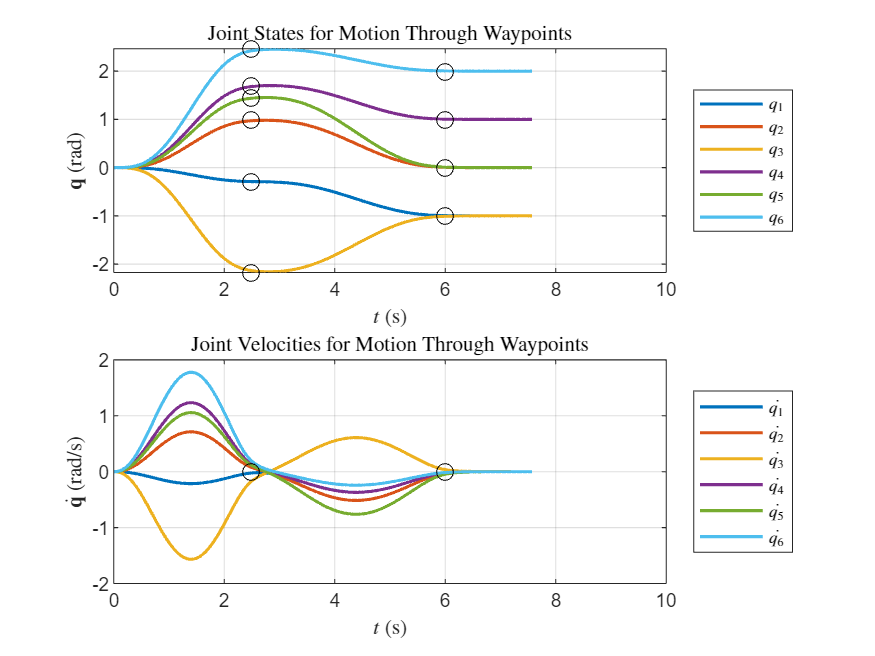

% Plot joint states
figure(2);

% Plot joint positions
subplot(2, 1, 1);
plot(timeStamp, jointStateStamped, 'LineWidth', 1.5);  % Plot joint positions
hold on;
for i = 1:size(q_targets, 1)
    plot(t_targets(i), q_targets(i, :), 'ko', 'MarkerSize', 8);  % Mark waypoints
end
hold off;

xlabel('$t$ (s)', 'Interpreter', 'Latex');
ylabel('$\mathbf{q}$ (rad)', 'Interpreter', 'Latex');
legend({'$q_1$', '$q_2$', '$q_3$', '$q_4$', '$q_5$', '$q_6$'}, 'Interpreter', 'Latex', 'FontSize', 8, 'Location', 'eastoutside');
title('Joint States for Motion Through Waypoints', 'Interpreter', 'Latex');
grid on;
xlim([0 10]); 

% Plot joint velocities
subplot(2, 1, 2);
plot(timeStamp, jointVelStamped, 'LineWidth', 1.5);  % Plot joint velocities
hold on;
for i = 1:size(q_targets, 1)
    plot(t_targets(i), qvel(i, :), 'ko', 'MarkerSize', 8);  % Mark waypoints for velocities
end
hold off;

xlabel('$t$ (s)', 'Interpreter', 'Latex');
ylabel('$\dot{\mathbf{q}}$ (rad/s)', 'Interpreter', 'Latex');
legend({'$\dot{q_1}$', '$\dot{q_2}$', '$\dot{q_3}$', '$\dot{q_4}$', '$\dot{q_5}$', '$\dot{q_6}$'}, 'Interpreter', 'Latex', 'FontSize', 8, 'Location', 'eastoutside');
title('Joint Velocities for Motion Through Waypoints', 'Interpreter', 'Latex');
grid on;
xlim([0 10]);  

#### 14.	Modify the joint trajectory from task 12 and perform task 12 and 13

Modify the joint trajectory command by imposing a velocity vector $$\dot{\mathbf{q}}_1=[-0.4 \ 0.0 \ 0.0 \ -0.3 \ 0.0 \ 0.0]$$ for the first way-point. Notice, that for a smooth motion the joint velocities $$\dot{q}_1,\dot{q}_4$$ should assume their maximum at the first way-point. The maximum velocity equals is twice as large as the average velocity given by 


$$\mathbf{q}_{avg}=\frac{\mathbf{q}_f-\mathbf{q}_i}{t_f}$$


in which $$q_f$$ denotes the final joint state, $$q_i$$ the initial joint state and $$t_f$$ the total time of motion. The commanded velocity at the final way-point $$\dot{\mathbf{q}}_2$$ should still be zero for all joints as the motion is supposed to stop at the end of the trajectory. The motion with corrected way-point velocities is shown in figure 5.

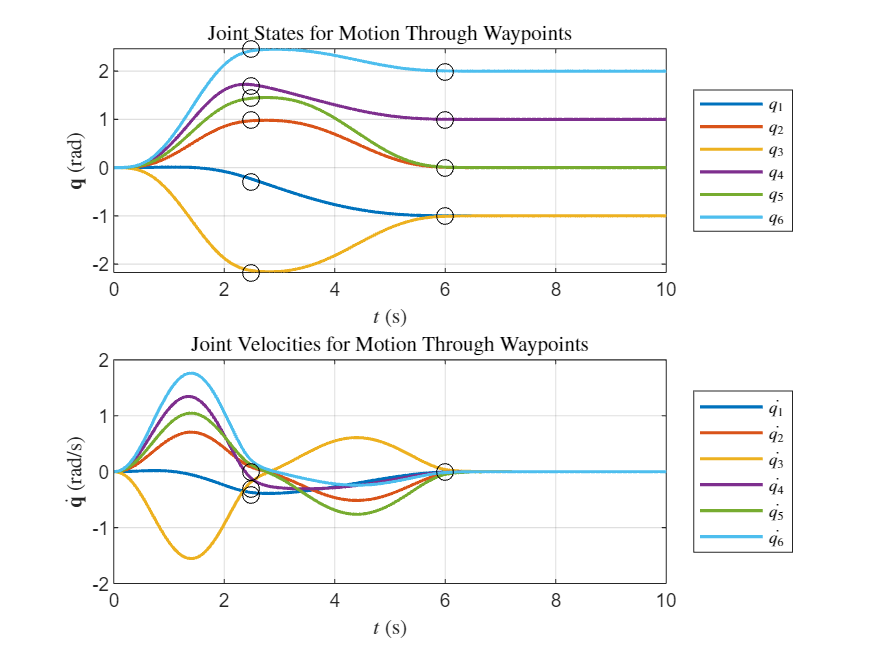

t_offset = 3; % Extra time buffer

% Move robot to home position
send(jointTrajectoryPub, JointVec2JointTrajectoryMsg(ur10, q_home, t_home));

% Wait for robot to reach home position before proceeding
pause(t_home + t_offset);  % Add offset time for smooth transition

% Define waypoints, time targets, and velocities
t_targets = [2.5; 6.0];   % Time to reach intermediate and final waypoints
qf = [-1 0 -1 1 0 2];     % Final waypoint configuration
q_targets = [q_target ; qf]; % Combine intermediate waypoint (q_target) and final waypoint (qf)

% Define initial velocity vector for the first waypoint
q1dot = [-0.4 0.0 0.0 -0.3 0.0 0.0]; % Velocity at the first waypoint
% Define velocities (set to zeros initially)
qvel = zeros(size(q_targets));  % Default to zero velocity

% Modify q1dot and q4dot to ensure smooth motion
qvel(1, :) = q1dot; % Apply q1dot to the first waypoint
qvel(end, :) = zeros(1, 6); % Zero velocity at the final waypoint (stopping point)

% Save trajectory parameters for Task 13
save('trajectory_params.mat', 'q_targets', 't_targets', 'qvel');  % Save waypoints, time targets, and velocities
% Load the previously saved trajectory parameters from Task 12
load('trajectory_params.mat', 'q_targets', 't_targets', 'qvel');
jointTrajectoryMsg = JointVec2JointTrajectoryMsg(ur10, q_targets, t_targets, qvel, zeros(size(q_targets)));
send(jointTrajectoryPub, jointTrajectoryMsg);

%Monitoring the Robot Motion
% Define rate and total duration
rate = 100; % Hz
rateObj = robotics.Rate(rate);

% Define total monitoring time
tf = t_targets(end) + 2.0;  % Add safety margin
rateObj.reset();  % Reset the rate object

% Preallocate arrays for monitoring data
N = tf * rate;  % Number of monitoring steps
timeStamp = zeros(N, 1);  % Timestamps
jointStateStamped = zeros(N, 6);  % Joint positions
jointVelStamped = zeros(N, 6);  % Joint velocities

% Store start time
jointStateMsg = jointStateSub.receive();  % Receive initial joint state message
t0 = double(jointStateMsg.Header.Stamp.Sec) + ...
     double(jointStateMsg.Header.Stamp.Nsec) * 10^-9;  % Convert to seconds

% Monitor and record joint states
for i = 1:N
    % Receive and convert joint state message
    jointStateMsg = jointStateSub.receive();    
    [jointState, jointVel] = JointStateMsg2JointState(ur10, jointStateMsg);
    
    % Store joint positions and velocities
    jointStateStamped(i, :) = jointState;  % Joint positions
    jointVelStamped(i, :) = jointVel;  % Joint velocities
    
    % Record timestamp
    current_time = double(jointStateMsg.Header.Stamp.Sec) + ...
                   double(jointStateMsg.Header.Stamp.Nsec) * 10^-9;  % Current time
    timeStamp(i) = current_time - t0;  % Relative time
    
    % Wait for the next iteration
    waitfor(rateObj);
end

% Plot joint states
figure(2);

% Plot joint positions
subplot(2, 1, 1);
plot(timeStamp, jointStateStamped, 'LineWidth', 1.5);  % Plot joint positions
hold on;
for i = 1:size(q_targets, 1)
    plot(t_targets(i), q_targets(i, :), 'ko', 'MarkerSize', 8);  % Mark waypoints
end
hold off;

xlabel('$t$ (s)', 'Interpreter', 'Latex');
ylabel('$\mathbf{q}$ (rad)', 'Interpreter', 'Latex');
legend({'$q_1$', '$q_2$', '$q_3$', '$q_4$', '$q_5$', '$q_6$'}, 'Interpreter', 'Latex', 'FontSize', 8, 'Location', 'eastoutside');
title('Joint States for Motion Through Waypoints', 'Interpreter', 'Latex');
grid on;
xlim([0 10]);  % Set x-axis limit from 0 to 9 seconds

% Plot joint velocities
subplot(2, 1, 2);
plot(timeStamp, jointVelStamped, 'LineWidth', 1.5);  % Plot joint velocities
hold on;
for i = 1:size(q_targets, 1)
    plot(t_targets(i), qvel(i, :), 'ko', 'MarkerSize', 8);  % Mark waypoints for velocities
end
hold off;

xlabel('$t$ (s)', 'Interpreter', 'Latex');
ylabel('$\dot{\mathbf{q}}$ (rad/s)', 'Interpreter', 'Latex');
legend({'$\dot{q_1}$', '$\dot{q_2}$', '$\dot{q_3}$', '$\dot{q_4}$', '$\dot{q_5}$', '$\dot{q_6}$'}, 'Interpreter', 'Latex', 'FontSize', 8, 'Location', 'eastoutside');
title('Joint Velocities for Motion Through Waypoints', 'Interpreter', 'Latex');
grid on;
xlim([0 10]);  % Set x-axis limit from 0 to 9 seconds

## Trajectory Control via Action Server and Client

#### 15.    Display the current list of actions on the ROS network

Display the current list of actions on the ROS network. Confirm that there is an action *'/ur10/vel_based_pos_traj_controller/follow_joint_trajectory' *and inspect the topic.

Notice, that goal message is of type *control_msgs/FollowJointTrajectoryGoal.*

% Verify the presence of a ROS action server for follow_joint_trajectory
% List all available actions on the ROS network
rosactionList = rosaction('list');
disp('List of available actions:');

List of available actions:


disp(rosactionList);

    {'/ur10/vel_based_pos_traj_controller/follow_joint_trajectory'}



% Inspect detailed information about the specific action
action_name = '/ur10/vel_based_pos_traj_controller/follow_joint_trajectory';
rosactionInfo = rosaction('info', action_name);
disp(['Information about action ', action_name, ':']);

Information about action /ur10/vel_based_pos_traj_controller/follow_joint_trajectory:


disp(rosactionInfo);

             ActionType: 'control_msgs/FollowJointTrajectory'
        GoalMessageType: 'control_msgs/FollowJointTrajectoryGoal'
    FeedbackMessageType: 'control_msgs/FollowJointTrajectoryFeedback'
      ResultMessageType: 'control_msgs/FollowJointTrajectoryResult'
           ActionServer: [1×1 struct]
          ActionClients: [0×1 struct]



% An action server provides a more robust framework.
% is about discovering and confirming the presence of the follow_joint_trajectory action server for the UR10 in ROS.

#### 16.	Instantiate an action client and an empty goal message

Instantiate an action client *followJointTrajectoryActClient*  for the action *'/ur10/vel_based_pos_traj_controller/follow_joint_trajectory'*.

% Instantiate an action client
disp(['Creating action client for: ', action_name]);

Creating action client for: /ur10/vel_based_pos_traj_controller/follow_joint_trajectory


followJointTrajectoryActClient = rosactionclient(action_name);
% Wait for the action server to be available
disp('Waiting for the action server to become available...');

Waiting for the action server to become available...


waitForServer(followJointTrajectoryActClient);
disp('Action server is available.');

Action server is available.


In case you have problems to initiate the action client, set the ROS_IP in your virtual machine by hand.

Therefore, get the IP of your VM with 

% hostname -I

and then set the ROS_IP with the shown IP

% export ROS_IP=<outputHostname>

Note that you have to do this for every new terminal window, or add it to your bashrc.

Alternatively, you can also install or use Matlab directly in the virtual machine (it is preinstalled on the VMs on the Retina PCs). The rosinit command simplifies then to "rosinit;"

#### 17.    Inspect the structure of the goal message

Inspect the structure of *followJointTrajectoryMsg*. The field *followJointTrajectoryMsg.Trajectory* corresponds to	the message type that you previously used for the topic interface. The message contains additional specification for path, goal and time tolerance, to monitor the accuracy of the commanded motion. 

% Create an empty goal message for the action
disp('Creating an empty goal message...');

Creating an empty goal message...


goalMsg = rosmessage(followJointTrajectoryActClient);
disp('Goal message successfully created.');

Goal message successfully created.



% Display the goal message structure for inspection
disp('Empty goal message structure:');

Empty goal message structure:


disp(goalMsg);

  ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [0×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message



#### 18.    Inspect the helper function 

The helper function 

`	function [ followJointTrajectoryMsg ] = JointVec2FollowJointTrajectoryMsg(robot, q, t, qvel, qacc)`

accepts a matrix of way-points *q* (optional joint velocities *qvel* and accelerations *qacc*) and a vector of time instances *t*  as input parameters and generates the corresponding *followJointTrajectoryMsg*.

followJointTrajectoryMsg = JointVec2FollowJointTrajectoryMsg_new(ur10, q, t, qvel, qacc);

% Print out or inspect the resulting message
disp('Constructed FollowJointTrajectoryGoal message:');

Constructed FollowJointTrajectoryGoal message:


disp(followJointTrajectoryMsg);

  ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [6×1 JointTolerance]
        GoalTolerance: [6×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message




% Show more details about the message
disp('Use showdetails to drill down into subfields:');

Use showdetails to drill down into subfields:


showdetails(followJointTrajectoryMsg);


  Trajectory           
    Header        
      Stamp      
        Sec  :  2135
        Nsec :  290000000
      Seq     :  0
      FrameId :  
    Points        
      - (1)
      TimeFromStart    
        Sec  :  0
        Nsec :  0
      Positions     :  [0, 0, 0, 0, 0, 0]
      Velocities    :  [-0.4, 0, 0, -0.3, 0, 0]
      Accelerations :  [0, 0, 0, 0, 0, 0]
      Effort        :  []
      - (2)
      TimeFromStart    
        Sec  :  2
        Nsec :  500000000
      Positions     :  [-0.2939059813737884, 0.9880528004043833, -2.171027884245231, 1.709917181489321, 1.463489064695678, 2.46388000623434]
      Velocities    :  [0, 0, 0, 0, 0, 0]
      Accelerations :  [0, 0, 0, 0, 0, 0]
      Effort        :  []
    JointNames :  {1}  shoulder_pan_joint   {2}  shoulder_lift_joint   {3}  elbow_joint   {4}  wrist_1_joint   {5}  wrist_2_joint   {6}  wrist_3_joint   
  PathTolerance        
    - (1)
    Name         :  shoulder_pan_joint
    Position     :  -1
    Velocity     :  -1
 

#### 19.    Follow a trajectory via the action client (blocking)

Generate a *followJointTrajectoryMsg* from the previous waypoint sequence and inspect the message structure.

Send the trajectory command message *followJointTrajectoryMsg* 

via the action client *followJointTrajectoryActClient* and wait for the action server to complete the trajectory. Inspect the *resultMsg* and *resultState*.

% Define waypoints and time targets
q_home = [0 0 0 0 0 0]; % Home position
q_final = [-1 0 -1 1 0 2]; % Final position
q_targets = [q_home; q_target; q_final];

t_targets = [0; 2.5; 6.0]; % Corresponding time stamps
assert(size(q_targets, 1) == numel(t_targets), '#waypoints and #time stamps do not match');

% Move to home configuration
disp('Moving robot to home configuration...');

Moving robot to home configuration...


t_home = 2.0;
t_offset = 1.0;
homeTrajectoryMsg = JointVec2JointTrajectoryMsg(ur10, q_home, t_home);
send(jointTrajectoryPub, homeTrajectoryMsg);
pause(t_home + t_offset);

% Create action msg
followJointTrajectoryMsg = rosmessage('control_msgs/FollowJointTrajectoryGoal');
trajectoryMsg = rosmessage('trajectory_msgs/JointTrajectory');
trajectoryMsg.JointNames = {'shoulder_pan_joint', 'shoulder_lift_joint', 'elbow_joint', 'wrist_1_joint', 'wrist_2_joint', 'wrist_3_joint'};
% Populate trajectory points
for i = 1:size(q_targets, 1)
    point = rosmessage('trajectory_msgs/JointTrajectoryPoint');
    point.Positions = q_targets(i, :);
    point.TimeFromStart = rosduration(t_targets(i));
    point.Velocities = zeros(1, 6)*0.1; % Ensure smooth motion
    trajectoryMsg.Points(i) = point;
end

followJointTrajectoryMsg.Trajectory = trajectoryMsg;
% Send message
[resultMsg, resultState] = followJointTrajectoryActClient.sendGoalAndWait(followJointTrajectoryMsg);

#### 20.	Follow a trajectory via the action client (non-blocking + monitoring)

Instead of waiting for the completion of the trajectory use `sendGoal` to continue. Replace the topic interface commands

`	jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10,q,t,qvel));`

with the equivalent action interface command

`	followJointTrajectoryMsg=JointVec2FollowJointTrajectoryMsg(ur10,q,t,qvel);`

`	followJointTrajectoryActClient.sendGoal(followJointTrajectoryMsg);`

Observe the command line output of the activation, feedback and result callback functions.	

% Define rate and total monitoring duration
rate = 100; % Hz
rateObj = robotics.Rate(rate);

% Define configurations
q_home = [0 0 0 0 0 0]; % Home configuration
qf = [-1 0 -1 1 0 2]; % Final configuration
send(jointTrajectoryPub, JointVec2JointTrajectoryMsg(ur10, q_home, t_home));

% Define waypoint sequence
q_targets = [q_target; qf]; % Final configuration

% Define time instances for waypoints
t_targets = [2.5; 6.0]; % Total trajectory time for smooth transitions

% Define initial velocity vector for the first waypoint
q1dot = [-0.4 0.0 0.0 -0.3 0.0 0.0]; % Velocity at the first waypoint

% Define velocities (set to zeros initially)
qvel = zeros(size(q_targets));  % Default to zero velocity

% Modify q1dot and q4dot to ensure smooth motion
qvel(1, :) = q1dot; % Apply q1dot to the first waypoint
qvel(end, :) = zeros(1, 6); % Zero velocity at the final waypoint (stopping point)

% Move robot back to home configuration using topic-based command
disp('Moving robot to home configuration...');

Moving robot to home configuration...


pause(4.0); % Allow motion to complete (add offset)

% Preallocate arrays for monitoring
tf = t_targets(end) + 1.0; % Add safety margin
N = tf * rate;
timeStamp = zeros(N, 1);
jointStateStamped = zeros(N, 6); % Record joint positions
jointVelStamped = zeros(N, 6); % Record joint velocities

% Store start time
jointStateMsg = jointStateSub.receive();
t0 = double(jointStateMsg.Header.Stamp.Sec) + ...
     double(jointStateMsg.Header.Stamp.Nsec) * 10^-9;

% Create followJointTrajectoryMsg from waypoints
disp('Creating and sending trajectory command via action client...');

Creating and sending trajectory command via action client...


followJointTrajectoryMsg = JointVec2FollowJointTrajectoryMsg(ur10, q_targets, t_targets, qvel, zeros(size(q_targets)));

% Send the trajectory command in a non-blocking way
followJointTrajectoryActClient.sendGoal(followJointTrajectoryMsg);

% Monitor and record the joint states while the trajectory is executed
disp('Monitoring joint states during execution...');

Monitoring joint states during execution...


for i = 1:N
    % Receive and convert joint state message
    jointStateMsg = jointStateSub.receive();
    [jointState, jointVel] = JointStateMsg2JointState(ur10, jointStateMsg);
    
    % Store joint positions and velocities
    jointStateStamped(i, :) = jointState;
    jointVelStamped(i, :) = jointVel;
    
    % Record timestamp
    current_time = double(jointStateMsg.Header.Stamp.Sec) + ...
                   double(jointStateMsg.Header.Stamp.Nsec) * 10^-9;
    timeStamp(i) = current_time - t0;
    
    % Wait for the next iteration
    waitfor(rateObj);
end

#### 21.    Plot the joint states and joint velocities

Plot the joint states and joint velocities for the commanded sequence of way-points as shown in figure 6.

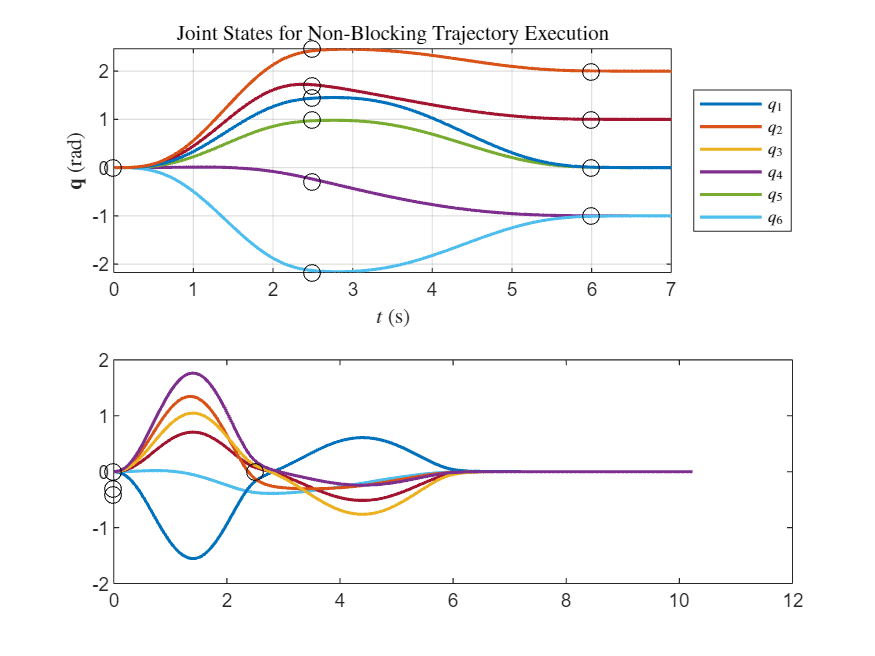

Index in position 1 exceeds array bounds. Index must not exceed 2.

figure(3);

% Plot joint positions
subplot(2, 1, 1);
plot(timeStamp, jointStateStamped, 'LineWidth', 1.5);
hold on;
for i = 1:size(q_targets, 1)
    plot(t_targets(i), q_targets(i, :), 'ko', 'MarkerSize', 8); % Mark waypoints
end
hold off;
xlabel('$t$ (s)', 'Interpreter', 'Latex');
ylabel('$\mathbf{q}$ (rad)', 'Interpreter', 'Latex');
legend({'$q_1$', '$q_2$', '$q_3$', '$q_4$', '$q_5$', '$q_6$'}, 'Interpreter', 'Latex', 'FontSize', 8, 'Location', 'eastoutside');
title('Joint States for Non-Blocking Trajectory Execution', 'Interpreter', 'Latex');
xlim([0,7]);
grid on;

% Plot joint velocities
subplot(2, 1, 2);
plot(timeStamp, jointVelStamped, 'LineWidth', 1.5);
hold on;
for i = 1:size(q_targets, 1)
    plot(t_targets(i), qvel(i,:), 'ko', 'MarkerSize', 8); % Mark waypoints
end

hold off;
xlabel('$t$ (s)', 'Interpreter', 'Latex');
ylabel('$\dot{\mathbf{q}}$ (rad/s)', 'Interpreter', 'Latex');
legend({'$\dot{q_1}$', '$\dot{q_2}$', '$\dot{q_3}$', '$\dot{q_4}$', '$\dot{q_5}$', '$\dot{q_6}$'},'Interpreter', 'Latex', 'FontSize', 8, 'Location', 'eastoutside');
title('Joint Velocities for Non-Blocking Trajectory Execution', 'Interpreter', 'Latex');
xlim([0,7]);
grid on;